# 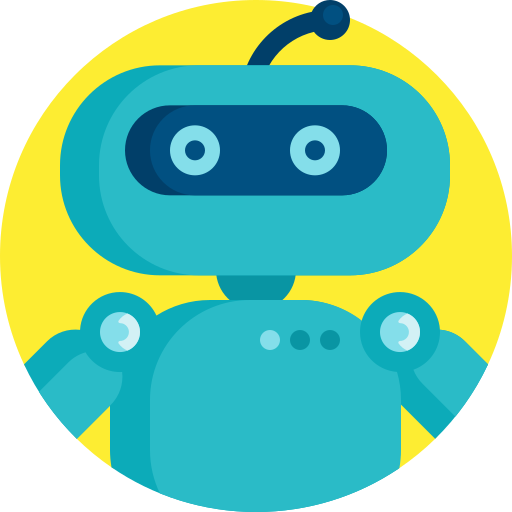

# **MEC4127F: Introduction to Robotics**

# Chapter 5: Robot arm kinematics

## 5.1 Introduction

This Chapter will apply some of the fundamental concepts developed in the prior chapters in order kinematically model robotic arms. We will explore both forward and inverse kinematics of robotic arms, and highlight the associated generalised use cases and challenges.

Before we can expect to plan and regulate a robot’s movement and/or functionality, we need to understand the causal relationship between the actuators that we can command (e.g. the wheel speeds of a car) and the resulting evolution of movement of the robotic platform (e.g. linear velocity described on a road). As we will show shortly, there are a range of considerations to keep in mind when trying to achieve some robotic goal. For this reason, we will first need to define some important spaces and quantities that we can use to better understand the limitations of our robotic platforms before asking them to do something that is not kinematically possible!

The task space and configuration space will be used to describe the two main* motion spaces* that we will work in. We will also briefly make use of the so-called actuator space to understand the space in which we can achieve actuation of our robot. We will then show that the forward and inverse kinematics of a robot describes the bidirectional mapping between the actuator space and task space in general.

### 5.1.2 The pose vector

So far we have made use of the transformation matrix when describing the pose of our robot in question, using the structure of ${^W{\bf T}_B} \in \text{SE}(3)$ when we are interesting in describing the world-frame pose in a six-dimensional space. As previously mentioned, the transformation matrix encodes the pose into a useful form that allows us to map frames and vectors in an efficient and systematic way. We can also represent the pose as a vector, made up of the position and orientation. 

When operating in $\text{SE}(3)$, our position will be three dimensional, whereas the orientation will have either three elements (e.g. exponential coordinates) or four elements (e.g. quaternions), depending on our choice of representing attitude. In the case of exponential coordinates, we can represent the full pose vector in $\text{SE}(3)$ as


$${^W\mathbf\xi}_B =
\left[\begin{array}{cc}    {^W{\bf t}_B} \\ \alpha{^W\hat{\bf v}     \\ \end{array}\right]
=
\left[\begin{array}{cc}    {{\bf t}_x} & {{\bf t}_y} & {{\bf t}_z} & \alpha v_x & \alpha v_y & \alpha v_z \end{array}\right]^T
\in \mathbb{R}^6,$$


where ${^W{\bf t}_B}=[t_x~~t_y~~t_z]^T$ describes the location of our robot in $\{W\}$ and $\alpha{^W\hat{\bf v}=\alpha[ v_x ~~  v_y ~~  v_z]^T$ provides the associated orientation descriptor. Note that the term ${\mathbf\xi}$ is pronounced "ksi".

The pose vector does not necessarily need to be described as a six-vector. Instead, the pose vector will conform to the size of the space that it is operating in. When operating in $\text{SE}(2)$, in other words, on a plane, our position will be two dimensional, and the orientation will be described by a single angle, $\psi$. In this case, we can represent the full pose vector in $\text{SE}(2)$ as


$${^W\mathbf\xi}_B =
\left[\begin{array}{cc}    {^W{\bf t}_B} \\ \psi     \\ \end{array}\right]
=
\left[\begin{array}{cc}    {{\bf t}_x} \\ {{\bf t}_y} \\ \psi \end{array}\right]
\in \mathbb{R}^3.$$


### 5.1.3 Robotics toolbox

This Chapter will make use of `MATLAB`'s [Robotics System Toolbox](https://in.mathworks.com/help/robotics/index.html) to generate various visualisations of robotic arms. The toolbox can also be used to determine relative poses of any one frame with respect to another in the robot and will serve useful in terms of understanding the kinematic relationships between all the links that make up a multi-body robotic arm. 

An example is given below, which will be explored in detail later on in the Chapter, as well in the relevant Virtual Lab. For now, feel free to play with the sliders!

l1 =0.5;
l2 =0.5;

robot = rigidBodyTree("DataFormat","column");
manipulatorBase = rigidBody('manipulatorBase');
%joint1
baseJoint = rigidBodyJoint('baseJoint','revolute');
baseJoint.JointAxis = [0 0 1];
baseJoint.HomePosition = 0;
p_joint1 = [0, 0, 0];
tform = trvec2tform(p_joint1);
setFixedTransform(baseJoint,tform);
manipulatorBase.Joint = baseJoint;
addBody(robot,manipulatorBase,'base');
%joint2 and link1
link1 = rigidBody('link1');
elbowJoint = rigidBodyJoint('elbowJoint','revolute');
elbowJoint.JointAxis = [0 0 1];
elbowJoint.HomePosition = 0;
p_joint2 = [l1, 0, 0];
tform2 = trvec2tform(p_joint2);
setFixedTransform(elbowJoint,tform2);
link1.Joint = elbowJoint;
addBody(robot,link1,'manipulatorBase');
%link2 and end-effector
link2 = rigidBody('link2');
endEffectorJoint = rigidBodyJoint('endEffectorJoint');
tform3 = trvec2tform([l2, 0, 0]);
setFixedTransform(endEffectorJoint,tform3);
link2.Joint = endEffectorJoint;
addBody(robot,link2,'link1');

alpha =56*pi/180;
beta =40*pi/180;
x = [alpha beta]';

fig = figure(1),clf;

fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 360 560 420]
       Units: 'pixels'

  Show all properties


show(robot,x,"Parent",axes(fig))

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


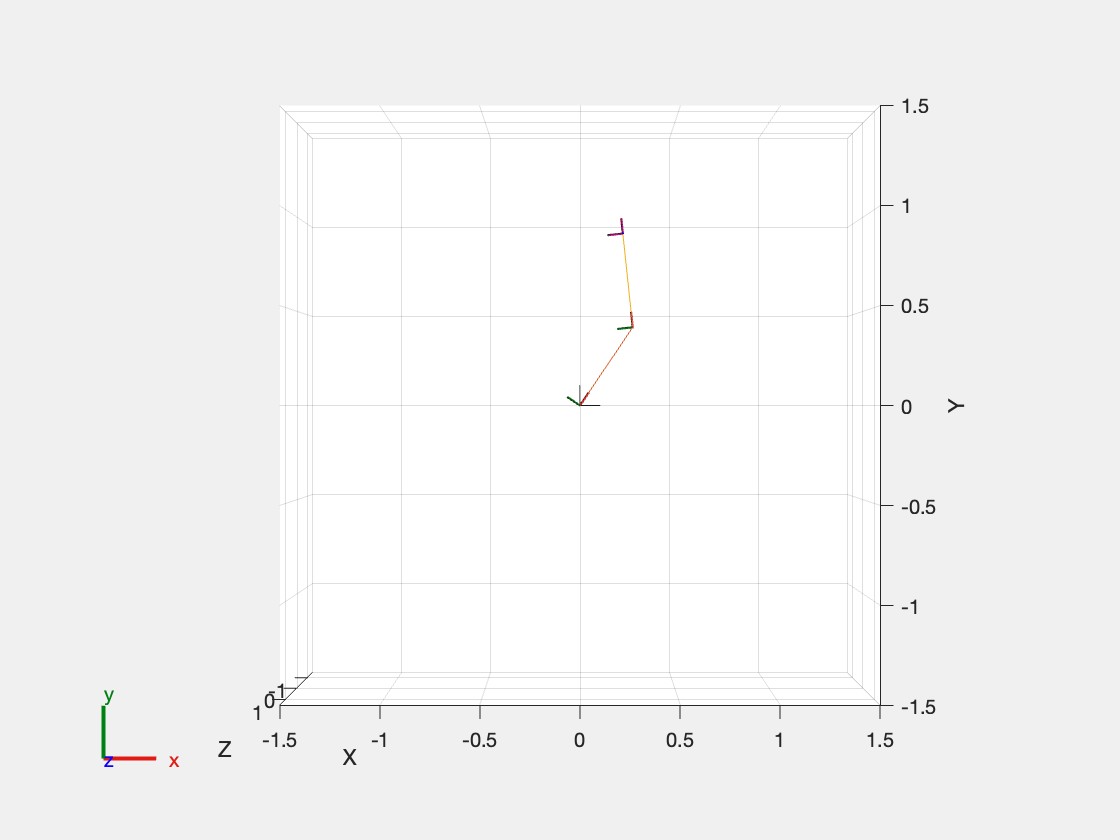

view(2)

## 5.2 Motion spaces

We will consider three **motion spaces** when dealing with the modelling of robotic platforms, namely:

- Task space — the vector space where we usually describe the pose of the robot.

- Configuration space — the vector space that uniquely and compactly describes the position of all points on the robot for a given configuration.

- Actuator space — the vector space that describes all independent actuator signals acting on the robotic platform.

As we will show in the following subsections, understanding these spaces, as well as how to map between them, allows us to do some useful things that will assist with both understanding the underlying mechanics of our robots, as well as assist later with trajectory generation and control design.

### 5.2.1 Task space

When we issue high-level commands to a robot, such as requesting it to move to a particular 3D position and/or orientation, we are operating in the **task space**, which we denote with the symbol $\mathcal{T}$. In other words, our understanding of how pose vector ${^W\mathbf\xi}_B$ represents the pose of $\{B\}$ with respect to $\{W\}$, which is predicated on affixing a reference frame on the robot body, is implicitly taking place in the task space (or operational space), namely


$${^W\mathbf\xi}_B \in \mathcal{T}.$$


One can imagine us similarly specifying a desired pose vector, ${^W\mathbf\xi}_B^*$, with the superscript $*$ indicating a reference quantity. This desired pose vector would then be framed as part of our robot's task, such as a wheeled robot parking in a specific configuration, defined by reference pose ${^W\mathbf\xi}_B^*$, which naturally is described in $\mathcal{T}$. How we actually make ${^W\mathbf\xi}_B\rightarrow{^W\mathbf\xi}_B^*$ comes down to the trajectory generation and control design, which we will discuss in a later chapter.

#### **Definition:** Task space

The **task space**, or operational space, is the space in which high-level motion and force commands are issued and executed.

We will denote the dimension of our task space as $\text{dim} ~\mathcal{T}$.The task at hand for the robot will vary depending on the application, so we can choose the effective dimensions of the task space. For example, a quadcopter that can experience arbitrary 3D translation and rotation will have a six-dimensional task space in general ($\text{dim} ~\mathcal{T}=6$), whereas a wheeled robot bound to a plane will have a three-dimensional task space ($\text{dim} ~\mathcal{T}=3$) — made up of an $x$-$y$ position and single angle describing the orientation. 

It is important to keep in mind that we as the engineers are providing the task to the to robot, so we can choose $\text{dim} ~\mathcal{T}$ where applicable. For example, if our wheeled robot is actually bound to a track that will not allow it to turn, then we can actually discard the orientation component from our task space to better describe the constraints of the project. 

### 5.2.2 Configuration space

The **configuration space**, or C-space, is an alternative way to fully describe the pose of a robot, albeit with the smallest set of parameters. We will denote the C-space with the symbol $\mathcal{C}$. The smallest set of parameters that describe $\mathcal{C}$ for the particular robot is known as the generalised coordinates.

#### **Definition:** Generalised coordinates

The **generalized coordinates** of a robot refers to the parameters that describe the configuration of the system relative to some reference configuration.

These generalised coordinates will uniquely define the resulting task space behaviour of the system. The robot configuration is described in the configuration space and is a complete specification of the position of every point of the robot. Any point in the configuration space can be mapped to a point in the task space, but the inverse is not true if physical constraints are applied to the robot, as we will show later.

The configuration of a robot is also related to the robot's *degrees of freedom*. In particular, the minimum number, $N$, of real-valued coordinates needed to represent the configuration of a robot is the number of degrees of freedom of the robot. As a result, the number of dimensions of the robot C-space will be equal to the degrees of freedom of the robot, namely


$$\text{dim}~\mathcal{C}=N.$$


With reference to Figure 5.1, the configuration of a hinged door can be completely described by a single angle, $\theta$, about its hinge. 

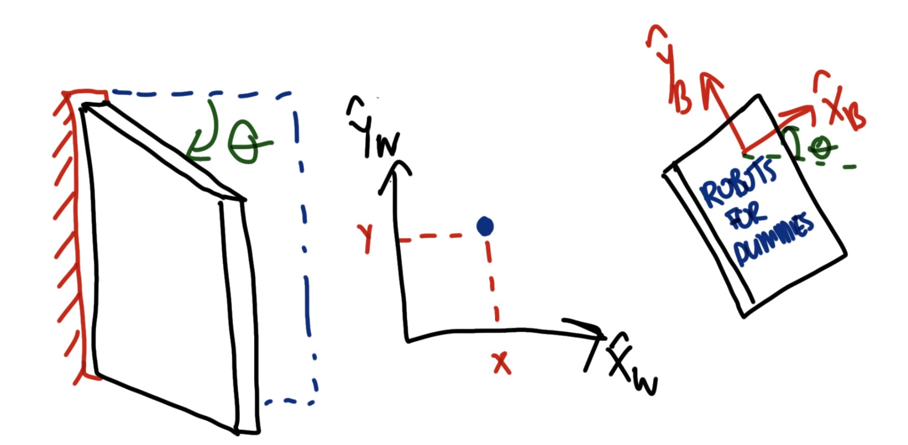

**Figure 5.1:** Arbitrary configuration and degrees of freedom of a door, point in a plane, and a book in a plane.

It follows that the door has a single degree of freedom, and therefore a one-dimensional C-space ($N=\text{dim} ~\mathcal{C}=1$). A point on a plane is described by the two principle components ($x$,$y$) and has two degrees of freedom, with a C-space that spans the $x-y$ plane ($N=\text{dim} ~\mathcal{C}=2$). The configuration of a book lying on a table is described by its location on the table ($x$,$y$), as well as its orientation, $\theta$. This infers that the book has three degrees of freedom ($N=\text{dim} ~\mathcal{C}=3$). 

In general, an unconstrained rigid body operating in SE(3) will have $\text{dim}~\mathcal{C}=6$. If we provide the condition that the rigid body is now constrained to a plane, i.e. in SE(2), the planar robot have $\text{dim}~\mathcal{C}=3$. By extension, it is easy show that the configuration space collapses to lower dimensions as a result of providing constraints to the robot.

Given a particular task, such as driving a wheeled robot from one corner of the room to another, we need to ensure that the corresponding configuration space has at least the same number of dimensions as that of the task space, namely


$$\text{dim}~\mathcal{C}\geq \text{dim}~\mathcal{T}.$$


If we instead had $\text{dim}~\mathcal{T}> \text{dim}~\mathcal{C}$, this would mean that the robot cannot access all points in the task space. While every point in the C-space can map to the task space, most points in the task space will not map to a point in $\mathcal{C}$. This could for example be representing a task space of $\mathcal{T}\subset \text{SE(3)}$ when our wheeled robot is bound to the $x-y$ plane and cannot change its height or roll/pitch angles. For the case of $\text{dim}~\mathcal{C}= \text{dim}~\mathcal{T}$, every point in the task space will be accessible by the robot. However, depending on the type of robot, any point in the task space may map to two points in the C-space. We will see this in action a bit later with the robotic arms in this Chapter. For the case of $\text{dim}~\mathcal{C}> \text{dim}~\mathcal{T}$, an infinite number of robot configurations will map to the same point in the task space. A good example is a snake-like robot with more than $6$ joints.

For unconstrained rigid-body robots in SE(3), as well robots that are constrained to a plane but otherwise have no physical restraints, the task space can be selected to match the configuration space without issue: $\mathcal{T}=\mathcal{C}$. A quadcopter, for example, has a 6-degree-of-freedom configuration space, and if the quadcopter is expected to operate in the entire space, it makes sense to allocate the task space to match that C-space. A wheeled robot bound to a plane operates in SE(3) but otherwise has no constraints, meaning that its configuration space, made up of $(x,y,\psi)$, can be set equal to its task space. The robotic arms in this Chapter have constraints enforced by joint motion, and as such, the configuration space will not be equivalent to the task space in general.

### 5.2.3 Actuator space

The **actuator space**, denoted with the symbol $\mathcal{A}$, describes the vector space of independent actuators that can affect change on the robot motion. A car, for example, will have two actuators — one to create forward acceleration, and one to adjust the steering angle — which means that $\text{dim} ~\mathcal{A}=2$. By contrast, a quadcopter has four motors that produce thrust, which would yield a four-dimensional actuator space ($\text{dim} ~\mathcal{A}=4$).

For certain robots, such as robot arms, the actuator space and C-space will be equivalent, namely $\mathcal{C}=\mathcal{A}$. However, other robots, such as wheeled robots, will not have this relationship, which is related to whether a robot is holonomic or non-holonomic (more on this later). The actuator space is very important, as this is the space that will ultimately be used to create or adjust the motion of our robot. As such, any desired actuator command must fall within our actuator space. Otherwise, we would be asking our robot to do something that is not physically possible. A simple example would be to expect our wheeled robot to traverse at a forward velocity far greater than the actuator limits.

As we will show in the subsequent section, when we define our forward kinematics, we will in general be determining the mapping from the actuator space to the task space of interest.


## 5.3 Types of joints

We will consider two main joint types when dealing with robotic arms in this course, namely

- revolute joints — allowing rotation about a fixed axis,

- prismatic joints — allowing translation along a fixed axis.

Both rotary and prismatic joints (see Figure 5.2) allow for only motion freedom between two bodies and can be thought of as providing five constraints on the motion of a rigid body, relative to another.

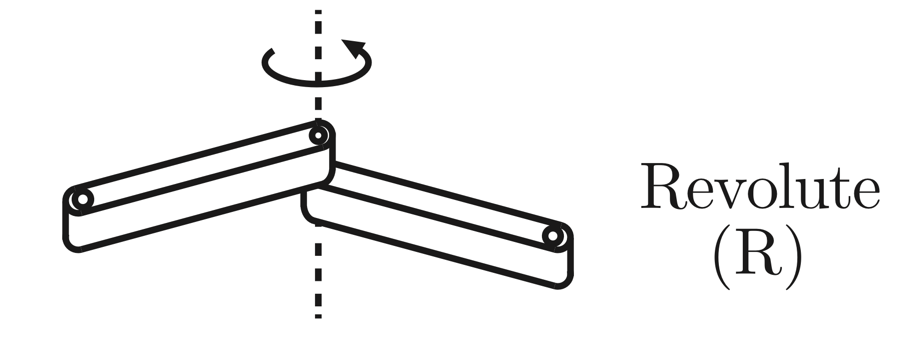     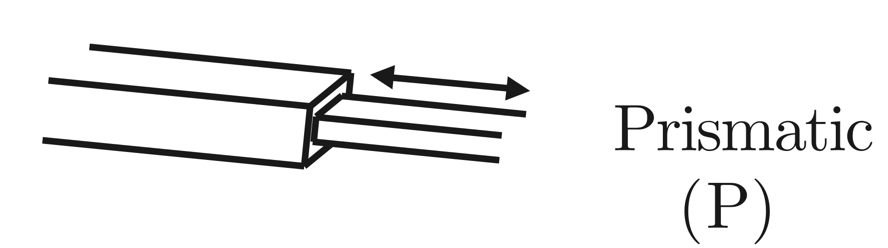

**Figure 5.2:** Revolute (R) and prismatic (P) joints.

As a result, each rigid body that has a joint acting about or along a fixed axis will have a single degree of freedom. By extension, a multi-body robot made up rigid $k$ links will have $k$ degrees of freedom and configuration/actuation space with $\text{dim} ~\mathcal{C}=\text{dim} ~\mathcal{A}=k$.

When dealing with multi-body robots with multiple joints, we will use R to refer to a revolute joint, and P to refer to a prismatic joint. For example, a robot with two revolute joints would be referred to in short as a 2R robot. If a robot for example has one revolute joint and one prismatic joint, then we can refer to the robot in short as an RP robot, with the first symbol indicating the joint closest to the base (the part of the robot fixed to a static frame.

### 5.3.1 Revolute joints

**Revolute joints**, commonly also referred to as *rotary joints*, allow one rigid body to rotate about a fixed point on another rigid body. This motion is usually facilitated using a motor and an embedded control scheme to ensure that the rotation angle is correct. We will assume in this course that the control problem has been solved when regulating joint position, and that we can arbitrarily choose the rotation angle of one rigid body with respect to another. 

The example code below use the robotics toolbox to generate a revolute joint that attaches a link to a fixed base.

robot = rigidBodyTree("DataFormat","column");
manipulatorBase = rigidBody('manipulatorBase');
%joint1
baseJoint = rigidBodyJoint('baseJoint','revolute');
baseJoint.JointAxis = [0 0 1];
baseJoint.HomePosition = 0;
p_joint1 = [0, 0, 0];
tform = trvec2tform(p_joint1);
setFixedTransform(baseJoint,tform);
manipulatorBase.Joint = baseJoint;
addBody(robot,manipulatorBase,'base');
%joint2 and link1
link1 = rigidBody('link1');
elbowJoint = rigidBodyJoint('elbowJoint','fixed');
p_joint2 = [.5, 0, 0];
tform2 = trvec2tform(p_joint2);
setFixedTransform(elbowJoint,tform2);
link1.Joint = elbowJoint;
addBody(robot,link1,'manipulatorBase');

x =29*pi/180;

fig = figure(1),clf;

fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 360 560 420]
       Units: 'pixels'

  Show all properties


show(robot,x,"Parent",axes(fig))

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


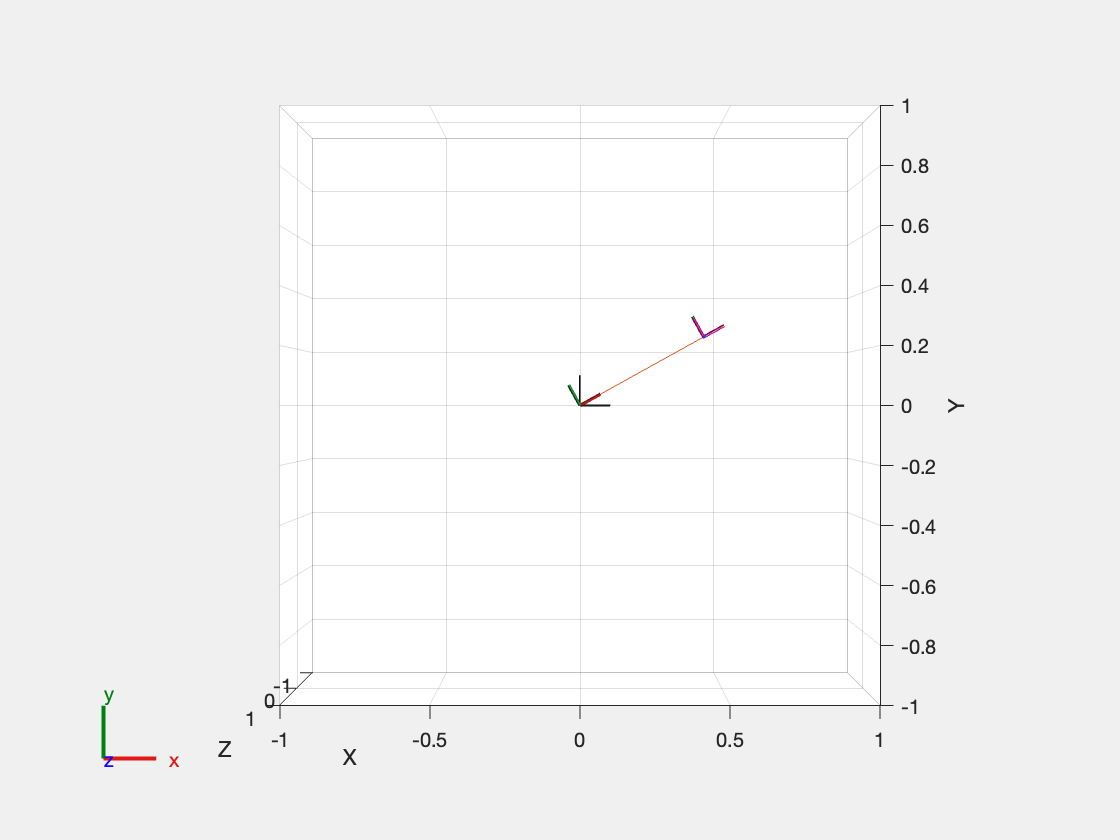

view(2)

### 5.3.2 Prismatic joints

**Prismatic joints** allow for linear motion between two rigid bodies along a fixed axis. This motion is usually achieved using a linear actuator. As with the revolute joints, we will assume in this course that the control problem has been solved and that we can arbitrarily choose the displacement of one rigid body with respect to another.

The example code below use the robotics toolbox to generate a prismatic joint that attaches a link to a fixed base.

robot = rigidBodyTree("DataFormat","column");
manipulatorBase = rigidBody('manipulatorBase');
%joint1
baseJoint = rigidBodyJoint('baseJoint','prismatic');
baseJoint.JointAxis = [1 0 0];
baseJoint.HomePosition = 0;
p_joint1 = [0, 0, 0];
tform = trvec2tform(p_joint1);
setFixedTransform(baseJoint,tform);
manipulatorBase.Joint = baseJoint;
addBody(robot,manipulatorBase,'base');
%joint2 and link1
link1 = rigidBody('link1');
elbowJoint = rigidBodyJoint('elbowJoint','fixed');
p_joint2 = [.2, 0, 0];
tform2 = trvec2tform(p_joint2);
setFixedTransform(elbowJoint,tform2);
link1.Joint = elbowJoint;
addBody(robot,link1,'manipulatorBase');

x =14*pi/180;

fig = figure(1),clf;

fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 360 560 420]
       Units: 'pixels'

  Show all properties


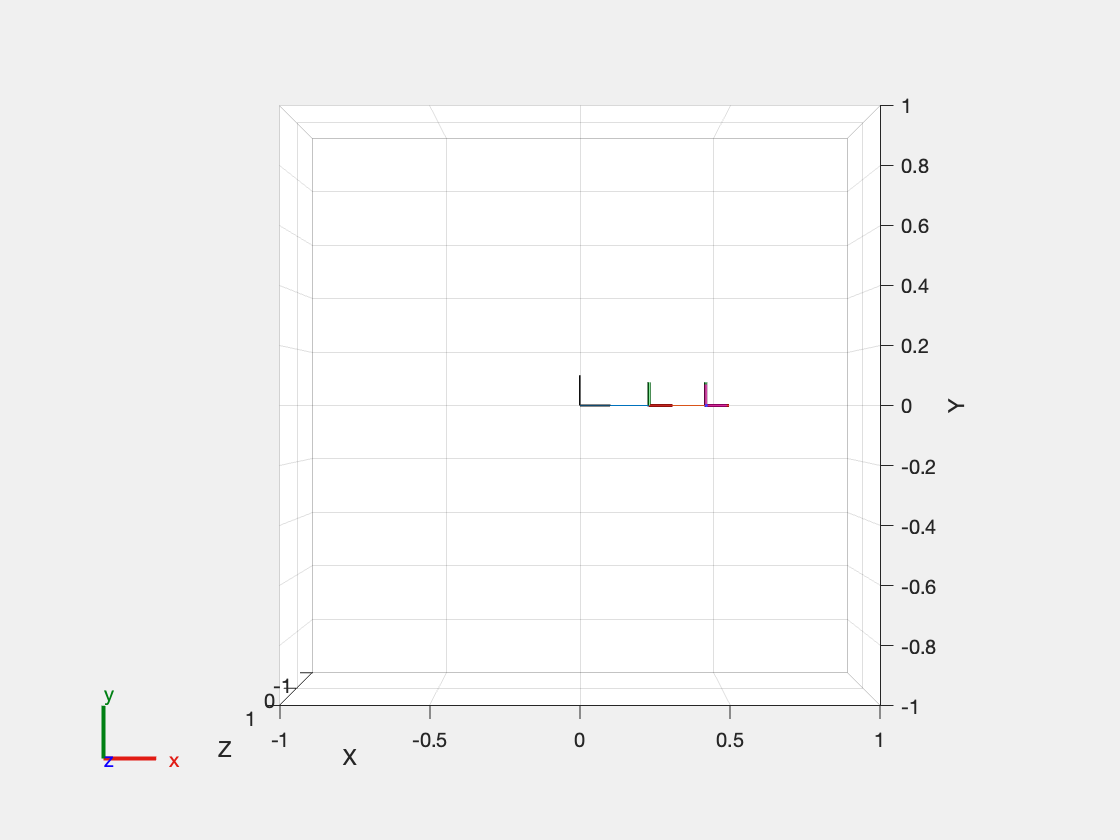

show(robot,x,"Parent",axes(fig));
view(2)

## 5.4 Forward kinematics of robot arms

Forward kinematics refers to the use of the kinematic equations of a robot to compute the task space output of the platform from specified values for the actuator parameters. Specifically, we intend to find  


$${^W\mathbf\xi}_B = {\mathbf\mathcal{K}}(\mathbf x)$$


where ${^W\mathbf\xi}_B\in \mathcal{T}$ is the pose vector description of $\{B\}$ with respect to $\{W\}$, $\mathbf x \in \mathcal{A}$ is a vector of the high-level controllable actuator states and ${\mathbf\mathcal{K}}$ is the forward kinematic mapping. Kinematics does not include the forces and torques that act on a body, but rather the resulting geometric behaviour of the system. Referring back to our motion spaces from Section 5.2, the forward kinematic equation maps the actuator space to the task space, namely


$${\mathbf\mathcal{K}}:~~\mathcal{A}\rightarrow \mathcal{T}.$$


For robotic arms, the actuator space is equivalent to the configuration space ($\mathcal{A}= \mathcal{C}.$), so it is often easier to think of the kinematics of robotic arms as mapping from the C-space to the task space: $\mathcal{C}\rightarrow \mathcal{T}$. 

We will begin with one of the most simplistic robot arms — a 2R planar manipulator arm, as exemplified in Figure 5.3. 

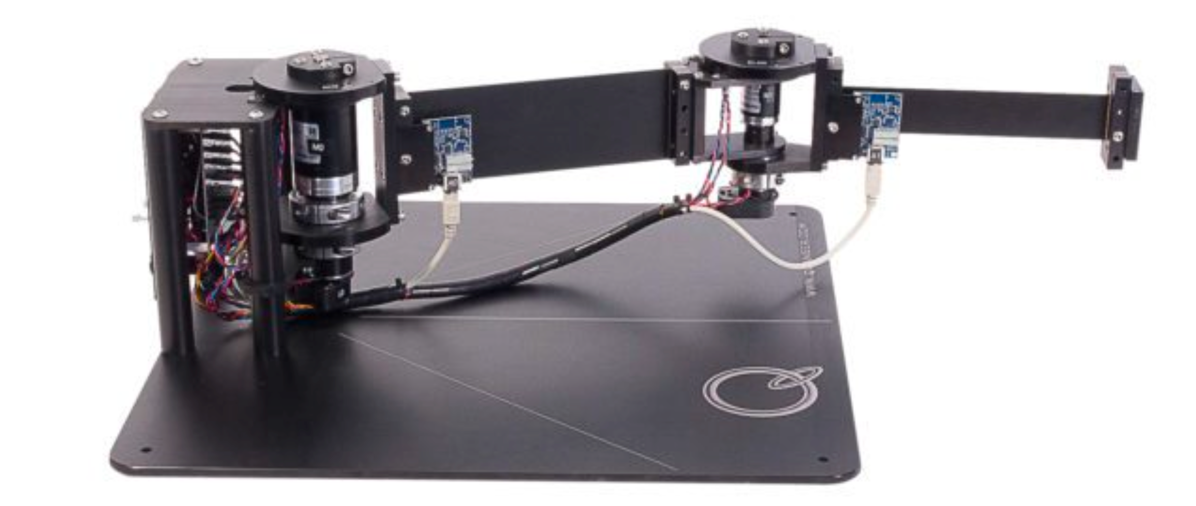

**Figure 5.3:** 2R planar manipulator from Quanser [[8]](https://www.quanser.com/products/2-dof-serial-flexible-link/), operating in the $\hat{\mathbf x}_W$-$\hat{\mathbf y}_W$ plane.

Note that the manipulator has $N=2$ degrees of freedom as its configuration space, made up of the two joint angles, has $\text{dim}~\mathcal{C}=2$. With reference to Figure 5.4, we have a manipulator robot made out of two links, two actuatable joints (indicated by the blue dots), and an end-effector (or grasping device). 

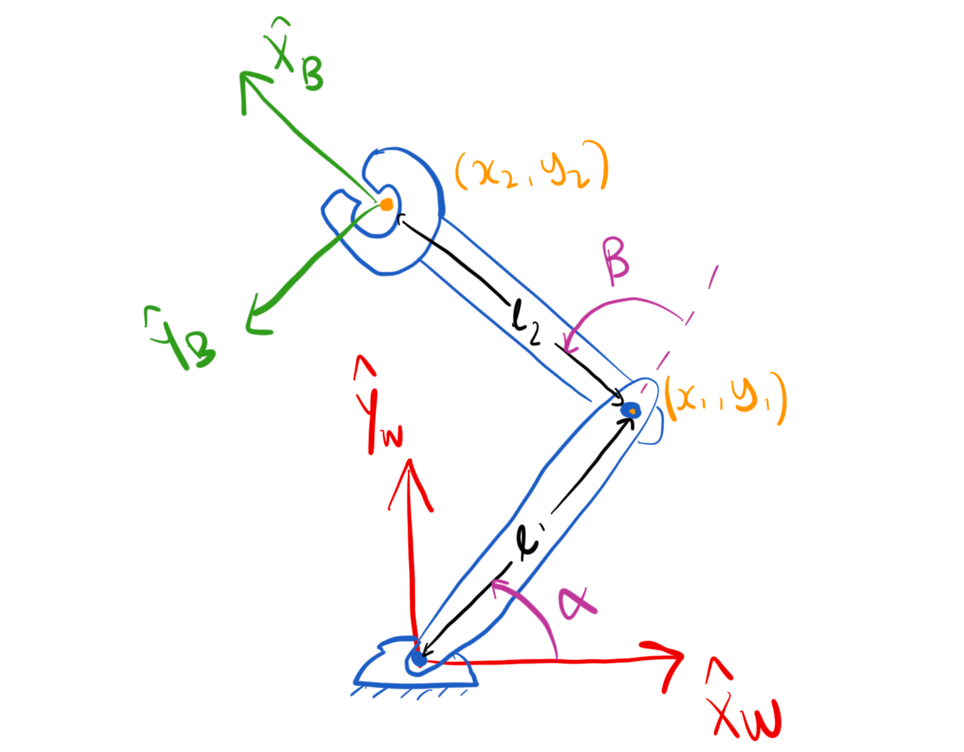

**Figure 5.4:** 2R Planar manipulator with rotary joints.
 

The robot is mounted to a static base, such that the base is always stationary. Moving from the base to the end-effector, the two link lengths are  $l_1$ and  $l_2$, respectively. The orientation of the first link, relative to $\hat{\bf x}_W$, is described using angle $\alpha$, and the orientation of the second link, relative to the *first link*, is $\beta$. Note that the description of our robot is such that there is no motion outside of the $\hat{\mathbf x}_W$-$\hat{\mathbf y}_W$ plane. In other words, all rotations occur parallel to the  $\hat{\mathbf z}_W$-axis using right-hand rule notation (anti-clockwise in this case for positive angles). 

Angles $\alpha$ and $\beta$ are set using motors, with the assumption that low-level control exists to accurately position the relative angles accordingly. As we are only considering the kinematics (not the dynamics), we do not need to concern ourselves with the torques experienced by the motors, or the inherent angular position control challenge that exists. 

It is common practice to place $\{B\}$ at our end-effector location (or gripper in this case), as we are distinctly interested in the end-effector pose when performing tasks such as picking up an object, or writing with a pen. Given that we are operating on a plane, we expect our end-effector pose vector to be ${^W\mathbf\xi}_B\in \mathbb{R}^{3}$ (our end-effector has a two-dimensional position and one-dimensional orientation), which means that $\text{dim}~\mathcal{T}=3$. However, we also know that our C-space has $\text{dim}~\mathcal{C}=2$, as a result of $\{\alpha,\beta\}$ fully describing the configuration of the robot. As such, because $\text{dim}~\mathcal{T}> \text{dim}\mathcal{C}$, the end-effector of our 2R robot arm will only be able to access points within a subset of the task space. As we will show later in this Section, a more sensible approach would be to either reduce the task space to $\text{dim}~\mathcal{T}=2$ (to allow full access of the task space), or else to add an independent actuator to the robot such that $\text{dim}~\mathcal{C}=\text{dim}~\mathcal{T}=3$.

The following subsections will show different approaches to deriving the forward kinematics. 

### 5.4.1 Derivation using trigonometry 

With reference to Figure 5.4, we start by calculating the position of the end of the first link, relative to the world frame, using trigonometry, which is simply


$$\begin{array}{cc}x_1 = l_1\cos{\alpha},\end{array}$$



$$\begin{array}{cc}y_1 = l_1\sin{\alpha}.\end{array}$$


The position of our end-effector is determined by providing the same formulation, and also taking into account its location relative to $\(x_1,y_1\)$:


$$\begin{array}{l}x_2 &= l_2\cos{(\alpha+\beta)}+x_1,\\
&=l_2\cos{(\alpha+\beta)}+l_1\cos{\alpha},
\end{array}$$



$$\begin{array}{ll}y_2 
&= l_2\sin{(\alpha+\beta)}+y_1,\\
&=l_2\sin{(\alpha+\beta)}+l_1\sin{\alpha}.
 \end{array}$$


The end-effector orientation simply follows as $\gamma=\alpha+\beta$ . The equations above describe the forward kinematic equations of the manipulator, as they relate the joint angles $\{\alpha,\beta\}$ to the world-frame position and orientation of the end-effector. Notably, this forward kinematic relationship also describes a mapping between our configuration space and task space. 

Given that the end-effector orientation is $\alpha+\beta$ , we can find the corresponding rotation matrix in SO(2) of


$$\begin{array}{cc}^W{\mathbf R}_B =     \left[\begin{array}{cccccccc}    \cos{(\alpha+\beta)} & -\sin{(\alpha+\beta)} \\    \sin{(\alpha+\beta)} & \cos{(\alpha+\beta)}  \end{array}\right]. \end{array}$$


The equations for $\{x_2,y_2\}$ can be combined to describe the end-effector position in $\mathbb{R}^2$ as


$$\begin{array}{cc}{^W{\mathbf t}_B} = \left[\begin{array}{cc}    l_2\cos{(\alpha+\beta)}+l_1\cos{\alpha} \\    l_2\sin{(\alpha+\beta)}+l_1\sin{\alpha}  \end{array}\right].\end{array}$$


We can construct our homogeneous transformation matrix that describes the world-frame pose of the end-effector in SE(2) as


$$\begin{array}{cc}^W{\mathbf T}_B = \left[\begin{array}{c|c}    ^W{\mathbf R}_B  & {^W{\mathbf t}_B} \\    \hline    {\bf 0}   & 1    \\ \end{array}\right] = \left[\begin{array}{cccccccccccccc}    \cos{(\alpha+\beta)} & -\sin{(\alpha+\beta)}  & l_2\cos{(\alpha+\beta)}+l_1\cos{\alpha} \\    \sin{(\alpha+\beta)} & \cos{(\alpha+\beta)}  & l_2\sin{(\alpha+\beta)}+l_1\sin{\alpha}\\    0 & 0  & 1    \\ \end{array}\right]. \end{array}$$


The pose vector is comprised of the position and orientation, and is given by


$$\begin{array}{cc}{^W\mathbf\xi}_B = \left[\begin{array}{cc}    l_2\cos{(\alpha+\beta)}+l_1\cos{\alpha} \\    l_2\sin{(\alpha+\beta)}+l_1\sin{\alpha} \\    \alpha+\beta    \\ \end{array}\right].\end{array}$$


### 5.4.2 Derivation using transformation matrices 

While direct trigonometry can be used to derive the forward kinematics of our system, this process can become onerous for more complex platforms that exist in three dimensions — you can imagine how confusing it would be if he had motion outside of the plane and a large amount of links and joints, making visualisation very tricky! This section will give a brief overview of how homogeneous transformation matrices can be used to derive the generalised forward kinematics. Note that although we largely apply this to robotic arms in SE(2), this method can be extended to any multi-body robot in SE(3) without loss of generality.

With reference to Figure 5.5, we are implicitly dealing with five different reference frames;

- frame $\{ W\}$ : attached to the table where the robot base is mounted.

- frame $\{ W^{'}\}$ : attached to the first controllable joint. Different to frame $\{W\}$ as a result of a rotation by $\alpha$ .

- frame $\{A\}$ : attached the end of the first link. Different to frame $\{ W^{'}\}$ as a result of a translation of $l_1$ .

- frame $\{ A^{'}\}$ : attached to the second controllable joint. Different to frame $\{ A\}$ as a result of a rotation by $\beta$ .

- frame $\{ B\}$ : attached to the end-effector. Different to frame $\{ A^{'}\}$ as a result of a translation of $l_2$ .

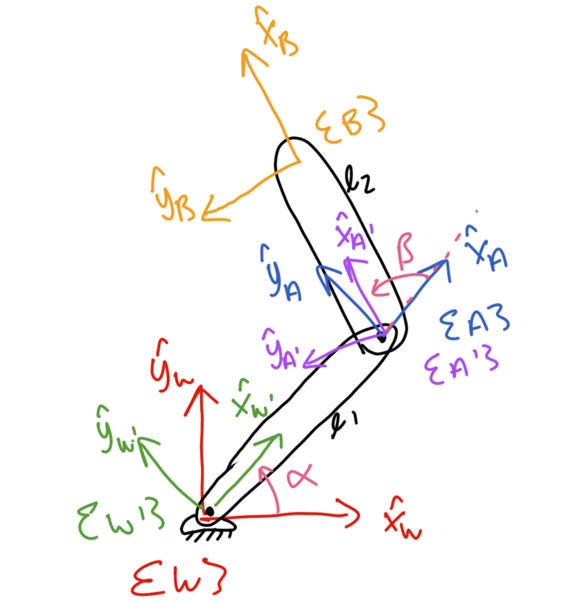

**Figure 5.5:** 2R Planar manipulator with intermediate reference frames shown.

We can therefore use our understanding of transformation matrices to chain together the transform describing the pose of $\{B\}$ with respect to $\{W\}$. Considering Figure 5.6, we can construct the encoded pose of $\{A\}$ using a sequential relative rotation and translation — a rotation about joint axis $\hat{\bf z}_W$, followed by a translation of  $l_1$ in the direction of $\hat{\bf x}_{W'}$.

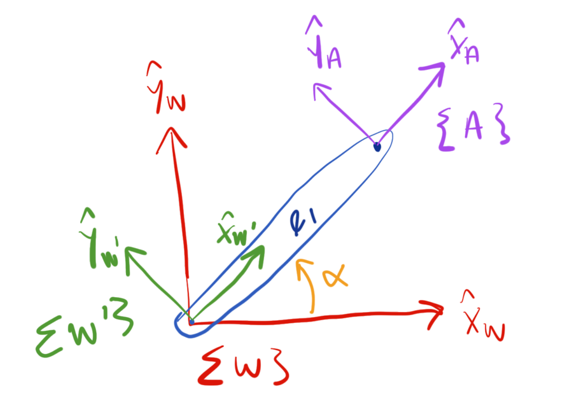

**Figure 5.6:** Planar manipulator with the three distinct reference frames shown.

The pose of $\{W'\}$ is related to $\{W\}$ based on a rotation about $\hat{\bf z}_W$ with angle $\alpha$, with the transformation matrix given by

  
$$\begin{array}{cc}^W{\mathbf T}_{W'} = \left[\begin{array}{c|c}    ^W{\mathbf R}_{W'}  & {\bf 0} \\    \hline    {\bf 0}   & 1    \\ \end{array}\right] = \left[\begin{array}{cccccccccccccc}    \cos{(\alpha)} & -\sin{(\alpha)}  & 0 \\    \sin{(\alpha)} & \cos{(\alpha)}  & 0\\    0 & 0  & 1    \\ \end{array}\right]. \end{array}$$


Frame $\{A\}$ is related to $\{W'\}$ by a translation of  $l_1$ in the direction of $\hat{\bf x}_{W'}$, and the corresponding transformation matrix is given by

  
$$\begin{array}{cc}^{W'}{\mathbf T}_{A} = \left[\begin{array}{c|c}    {\bf I}  & {^{W'}{\bf t}_A} \\    \hline    {\bf 0}   & 1    \\ \end{array}\right] = \left[\begin{array}{cccccccccccccc}    1 & 0  & l_1 \\   0 & 1  & 0\\    0 & 0  & 1    \\ \end{array}\right]. \end{array}$$


Frame $\{A\}$ can then be described with respect to $\{W\}$ by chaining the two transformation matrices together, namely


$$\begin{array}{ll}
{^W{\mathbf T}_{A}}
&=&{^W{\mathbf T}_{W'}}{^{W'}{\mathbf T}_{A}},\\
&=& \left[\begin{array}{cccccccccccccc}    \cos{(\alpha)} & -\sin{(\alpha)}  & 0 \\    \sin{(\alpha)} & \cos{(\alpha)}  & 0\\    0 & 0  & 1    \\ \end{array}\right] \left[\begin{array}{cccccccccccccc}    1 & 0  & l_1 \\   0 & 1  & 0\\    0 & 0  & 1    \\ \end{array}\right],\\
&=& \left[\begin{array}{cccccccccccccc}    \cos{(\alpha)} & -\sin{(\alpha)}  & l_1\cos{(\alpha)} \\    \sin{(\alpha)} & \cos{(\alpha)}  & l_1\sin{(\alpha)}\\    0 & 0  & 1    \\ \end{array}\right].
\end{array}$$


If we are interested in attached a second link to the end of the first link, as in the case of Figure 5.5, we can repeat the same process as above and ensure that the pose information of the second link is described with respect to $\{A\}$. Specifically, following the same logic as above, the pose of $\{B\}$ with respect to $\{A\}$ is given by


$$\begin{array}{ll}
{^A{\mathbf T}_{B}}
&=&{^A{\mathbf T}_{A'}}{^{A'}{\mathbf T}_{B}},\\
&=& \left[\begin{array}{cccccccccccccc}    \cos{(\beta)} & -\sin{(\beta)}  & 0 \\    \sin{(\beta)} & \cos{(\beta)}  & 0\\    0 & 0  & 1    \\ \end{array}\right] \left[\begin{array}{cccccccccccccc}    1 & 0  & l_2 \\   0 & 1  & 0\\    0 & 0  & 1    \\ \end{array}\right],\\
&=& \left[\begin{array}{cccccccccccccc}    \cos{(\beta)} & -\sin{(\beta)}  & l_2\cos{(\beta)} \\    \sin{(\beta)} & \cos{(\beta)}  & l_2\sin{(\beta)}\\    0 & 0  & 1    \\ \end{array}\right].
\end{array}$$


Given that we now know ${^W{\mathbf T}_{A}}$ and ${^A{\mathbf T}_{B}}$, we can multiply the two together to obtain the world-frame pose of $\{B\}$:


$$\begin{array}{ll}
{^W{\mathbf T}_{B}}
&=&{^W{\mathbf T}_{A}}{^{A}{\mathbf T}_{B}},\\

&=& \left[\begin{array}{cccccccccccccc}    \cos{(\alpha)} & -\sin{(\alpha)}  & l_1\cos{(\alpha)} \\    \sin{(\alpha)} & \cos{(\alpha)}  & l_1\sin{(\alpha)}\\    0 & 0  & 1    \\ \end{array}\right]\left[\begin{array}{cccccccccccccc}    \cos{(\beta)} & -\sin{(\beta)}  & l_2\cos{(\beta)} \\    \sin{(\beta)} & \cos{(\beta)}  & l_2\sin{(\beta)}\\    0 & 0  & 1    \\ \end{array}\right],\\
&=&  \left[\begin{array}{cccccccccccccc}    \cos{(\alpha+\beta)} & -\sin{(\alpha+\beta)}  & l_2\cos{(\alpha+\beta)}+l_1\cos{\alpha} \\    \sin{(\alpha+\beta)} & \cos{(\alpha+\beta)}  & l_2\sin{(\alpha+\beta)}+l_1\sin{\alpha}\\    0 & 0  & 1    \\ \end{array}\right].
\end{array}$$


Notice that this result matches that of Section 5.3.1. The important distinction is that this approach, using transformation matrices, can easily be extended to any number of joint rotations, including rotations out of the current plane. 

#### Example: Forward kinematics of a 2R robot arm

The code below simulates up a 2R robot arm with adjustable link lengths and joint angles. 

l1 =0.5;
l2 =0.5;

robot = rigidBodyTree("DataFormat","column");
manipulatorBase = rigidBody('manipulatorBase');
%joint1
baseJoint = rigidBodyJoint('baseJoint','revolute');
baseJoint.JointAxis = [0 0 1];
baseJoint.HomePosition = 0;
p_joint1 = [0, 0, 0];
tform = trvec2tform(p_joint1);
setFixedTransform(baseJoint,tform);
manipulatorBase.Joint = baseJoint;
addBody(robot,manipulatorBase,'base');
%joint2 and link1
link1 = rigidBody('link1');
elbowJoint = rigidBodyJoint('elbowJoint','revolute');
elbowJoint.JointAxis = [0 0 1];
elbowJoint.HomePosition = 0;
p_joint2 = [l1, 0, 0];
tform2 = trvec2tform(p_joint2);
setFixedTransform(elbowJoint,tform2);
link1.Joint = elbowJoint;
addBody(robot,link1,'manipulatorBase');
%link2 and end-effector
link2 = rigidBody('link2');
endEffectorJoint = rigidBodyJoint('endEffectorJoint');
tform3 = trvec2tform([l2, 0, 0]);
setFixedTransform(endEffectorJoint,tform3);
link2.Joint = endEffectorJoint;
addBody(robot,link2,'link1');

alpha =68*pi/180;
beta =-20*pi/180;
x = [alpha beta]';

fig = figure(1),clf;

fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 360 560 420]
       Units: 'pixels'

  Show all properties


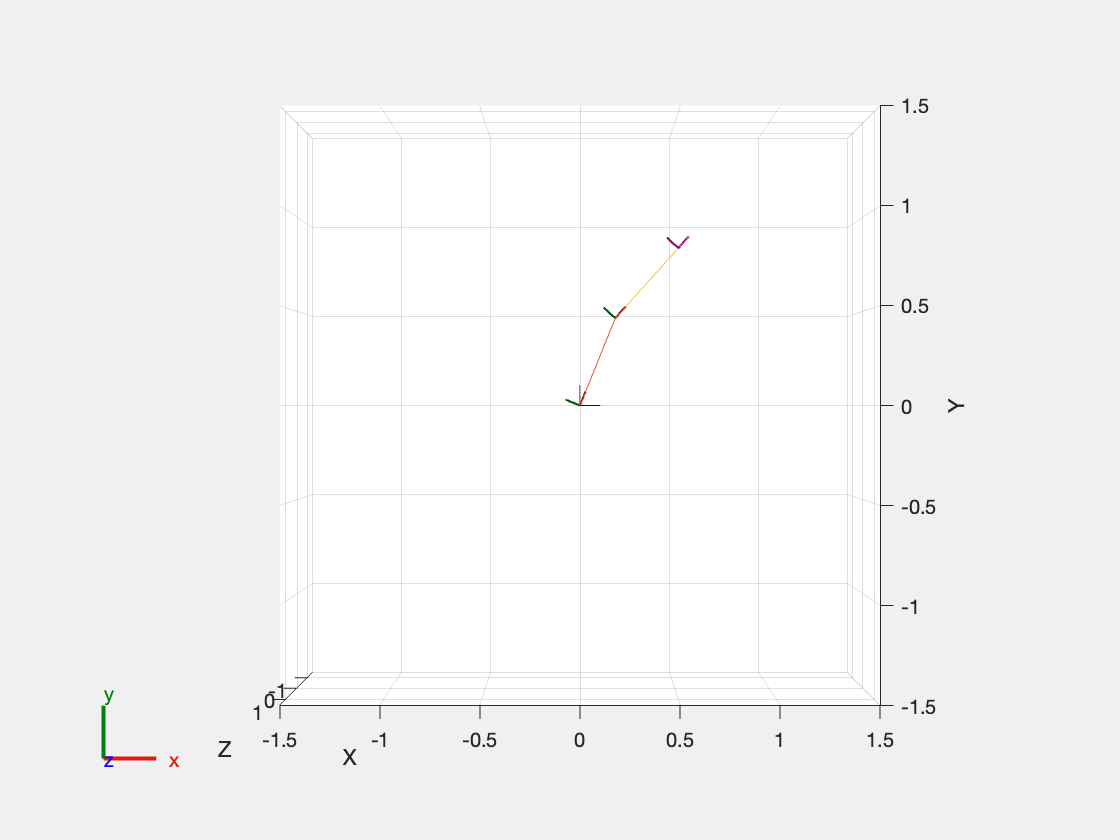

show(robot,x,"Parent",axes(fig));
view(2)

The code below generates a visualisation of the configuration space, spanned by $\{\alpha,\beta\}$, and task space when spanned by the world-frame end-effector position $(x,y)$.

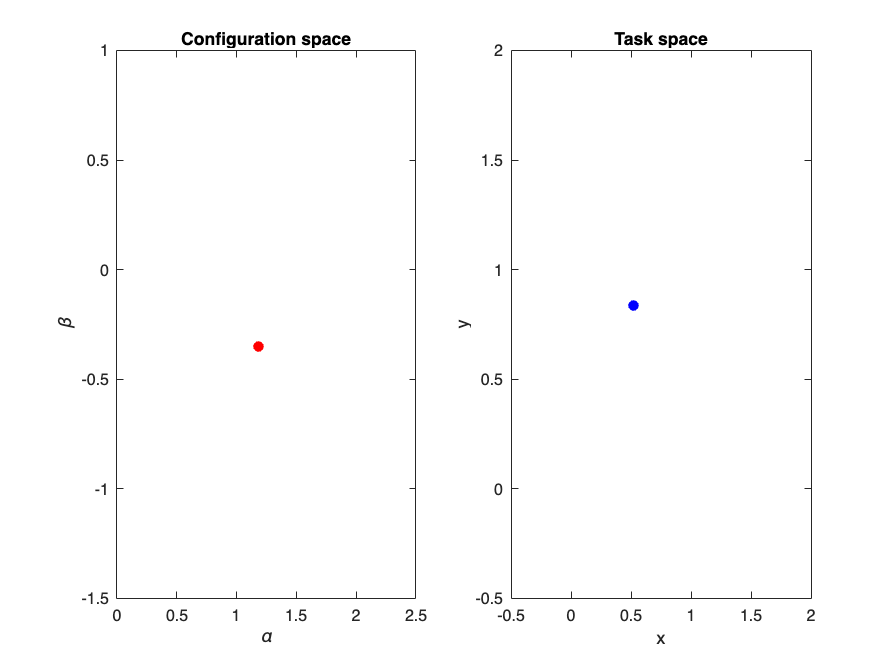

T_ = getTransform(robot, x, 'link2');
x = T_(1,4);
y = T_(2,4);

figure(2)
subplot(1,2,1),plot(alpha,beta,'ro',MarkerFaceColor='r'),xlabel('\alpha'),ylabel('\beta'),title('Configuration space')
subplot(1,2,2),plot(x,y,'bo',MarkerFaceColor='b'),xlabel('x'),ylabel('y'),title('Task space')

### 5.4.3 Workspace

One thing that we need to be aware of is the spatial limitations of the end-effector as a result of our actuators and link lengths, as they fundamentally determine the points in the task space that the end-effector can access.

The configuration space is given with respect to the robot's joints and allows us to calculate the **workspace** of the end-effector, i.e., the physical space it can reach. Specifically, if we were to run through every combination of allowable joint angles and then use our forward kinematic equation to calculate the corresponding pose of our end-effector, we would eventually sketch out the workspace — the *accessible* task space of the end-effector. The workspace is therefore a subset of the task space of choice.

Figure 5.7 below shows an example of a 2R robot arm's workspace when (a) $l_1=l_2$, and (b) $l_1>l_2$, which describes the set of all $(x,y)$ coordinates that the end-effector can obtain.

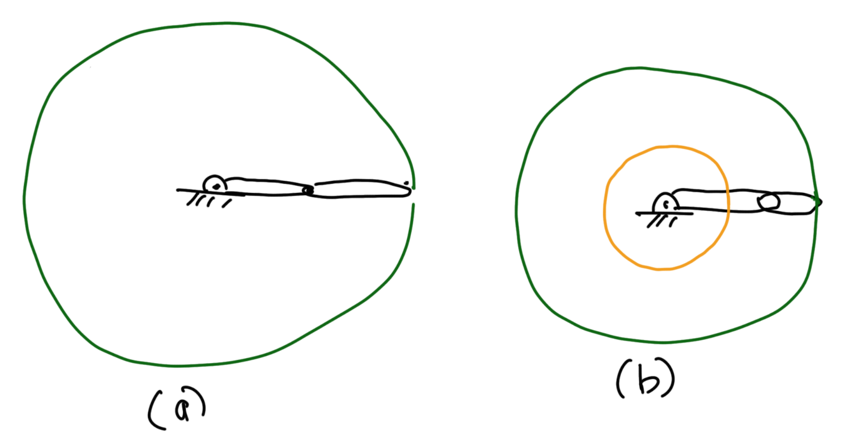

**Figure 5.7: **Workspace of a 2R robot when (a) $l_1=l_2$, and (b) $l_1>l_2$.

Robots will commonly be limited to a finite workspace. For example, the workspace of a car-like robot will be the surface that it can traverse on and will not include inaccessible areas such as the sea, whereas a quadrotor will not be limited to flat surfaces but will have a maximum altitude that it cannot exceed. It is important to understand the workspace limitations of our robot, so that we do not ever ask it to operate outside of it!

### 5.4.4 Adding additional joints

The 2R robot arm is a good starting point for understanding forward kinematics, but the workspace is limited to a disc. Additionally, as previously stated, the configuration space of a 2R robot arm has $\text{dim}~\mathcal{C}=2$, which is less than a task space of $\mathcal{T}\subset SE(2)$. In other words, one is not able to achieve arbitrary poses with the end-effector, which will be demonstrated in detail in Section 5.6. A logical solution to this would be to add an additional joint to the 2R robot, which can take the form a of a revolute or prismatic joint.

#### 5.4.4.1 Adding a third revolute joint

In the case of adding a revolute joint, the process to follow is identical to the previous section. First, the transformation matrix describing the additional joint is specified with respect to the frame where the joint is being attached, followed by calculating the transformation matrix of the newly added frame with respect to $\{W\}$. Based on Section 5.4.2 a revolute joint and link will have a relative pose of


$$\begin{array}{ll}
{^{\{k-1\}}{\mathbf T}_{\{k\}}}
&=& \left[\begin{array}{cccccccccccccc}    \cos{(\theta_k)} & -\sin{(\theta_k)}  & l_k\cos{(\theta_k)} \\    \sin{(\theta_k)} & \cos{(\theta_k)}  & l_k\sin{(\theta_k)}\\    0 & 0  & 1    \\ \end{array}\right],
\end{array}$$


where link $k$ is being attached to link $k-1$ with a distance of $l_k$ away from frame $\{k-1\}$ and with a relative angle of $\theta_k$. Note that if $l_k=0$ then the additional link is actually just a joint that is located at the origin of frame $\{k-1\}$ with a relative angle of $\theta_k$.

The world-frame pose of $\{k\}$ follows as


$$\begin{array}{ll}
{^{W}{\mathbf T}_{\{k\}}}=
{^{W}{\mathbf T}_{\{k-1\}}}
{^{\{k-1\}}{\mathbf T}_{\{k\}}}
&=& {^{W}{\mathbf T}_{\{k-1\}}}\left[\begin{array}{cccccccccccccc}    \cos{(\theta_k)} & -\sin{(\theta_k)}  & l_k\cos{(\theta_k)} \\    \sin{(\theta_k)} & \cos{(\theta_k)}  & l_k\sin{(\theta_k)}\\    0 & 0  & 1    \\ \end{array}\right].
\end{array}$$


#### 5.4.4.1 Adding a prismatic joint

In the case of adding a prismatic joint, the process to follow is similar to the previous section, with the key difference that the relative motion is a translation instead of a rotation. Given the addition of link $k$, which has a prismatic actuator, the corresponding relative transformation matrix with respect to link $k-1$ is given as


$$\begin{array}{ll}
{^{\{k-1\}}{\mathbf T}_{\{k\}}}
&=& \left[\begin{array}{cccccccccccccc}    1 & 0  & \Delta x_k \\    0 & 1  & \Delta y_k\\    0 & 0  & 1    \\ \end{array}\right],
\end{array}$$


where $\Delta x_k$ describes the translational motion parallel to $\hat{\bf x}_{\{k-1\}}$ and $\Delta y_k$ describes the translational motion parallel to $\hat{\bf y}_{\{k-1\}}$. Note that the transformation matrix implies that no incremental rotation is taking place.

The world-frame pose of $\{k\}$ follows as


$$\begin{array}{ll}
{^{W}{\mathbf T}_{\{k\}}}=
{^{W}{\mathbf T}_{\{k-1\}}}
{^{\{k-1\}}{\mathbf T}_{\{k\}}}
&=& {^{W}{\mathbf T}_{\{k-1\}}}\left[\begin{array}{cccccccccccccc}    1 & 0  & \Delta x_k \\    0 & 1  & \Delta y_k\\    0 & 0  & 1    \\ \end{array}\right].
\end{array}$$


## 5.5 Holonomic and non-holonomic robots

Using our results from the previous sections, we were able to determine that our 2R robot pose is uniquely defined by the two joint angles $\{\alpha,\beta\}$. These joint angles can be measured using encoders or potentiometers, and assuming the sensors possess sufficient resolution (and the links remain rigid with no out of plane motion), we will have an accurate description of our end-effector pose. As we will see later, the forward kinematic challenge for a wheeled robot is a bit more involved. We can still use encoders to measure our robot wheel velocity and orientation, but the displacement of the robot in the  $\hat{\mathbf x}_W$ - $\hat{\mathbf y}_W$ plane will be the accumulation (or integration) of said wheel orientations. An important note is that for so-called **non-holonomic** systems, it is not sufficient to simply measure the distance that each wheel has travelled, but also *when* each movement was executed. 

The 2R robotic arm that we have been mainly considering is **holonomic**, as each joint position combination uniquely describes the end-effector pose in $\{W\}$. In other words, there is an algebraic relationship between the joint angles and end-effector position. For example, for  $\alpha=\beta=0$ , the position of the end-effector always equals  $(l_1+l_2,0)$ , regardless of the trajectory that the end-effector followed prior to this point. Another way to think of holonomic systems is that they are able to instantaneously move in any direction of their configuration space. The robot arm can at any time increase or decrease either of its joint angles, so there is no limitation on its directional movement in C-space. The only exception is when the robot is in a singularity (for example when the robot arm is straight, thereby preventing motion in that direction).

A conventional wheeled robot is an example of a non-holonomic vehicle. The configuration space is made up of the position and orientation — $(x,y,\psi)$, but wheeled robots cannot traverse in the direction of the wheel axis, only perpendicular to it. As a result, one cannot instantaneously move in any direction in the C-space of a conventional wheeled robot. When there are limitations on how a robot can move in its C-space, this is referred to as a *non-holonomic kinematic constraint*. 

#### **Definition:** Non-holonomic kinematic constraint

A *non-holonomic kinematic constraint* is a kinematic constraint that is a function of "derivatives of positional variables" and cannot be integrated to provide a constraint in terms of positional variables. 

A non-holonomic constraint does not limit the accessible configurations, but limits the paths that can be followed to reach them. A non-holonomic kinematic constraint relies on a differential relationship, such as requiring the derivative of a position, which means that the constraint cannot be represented at the position level (preventing a direct mapping to the task space). For this reason, non-holonomic systems are often referred to as *non-integrable* systems.

## 5.6 Inverse kinematics of a robot arms

The forward kinematic construct allowed us to find  ${^W\mathbf\xi}_B = {\mathbf\mathcal{K}}(\mathbf x)$ for our manipulator robot and this informs us of the system behaviour and gave us a mapping from the C-space to the task space: 

$\mathcal{K}:\mathcal{C}\rightarrow\mathcal{T}$. 

This mapping allowed us to take ${\bf x}\in \mathcal{C}$ and map it to a unique point $(x,y,\psi)\in \mathcal{T}$. 

Moving from analysis to synthesis, if we are interested in achieving a desired pose in $\mathcal{T}$ (e.g. position our end-effector to grab a ball defined in the world-frame), we would need to find the corresponding actuator states that can place it there. In other words, we would need to invert our kinematic mapping that we have just developed so that we can solve for the actuator parameters, namely  ${\mathbf x}={\mathbf\mathcal{K}}^{-1}({^W\mathbf\xi}_B)$ . This inverse mapping would then indicate the configuration required within the C-space in order to achieve the desired pose (assuming $\text{dim}~\mathcal{C}\geq \text{dim}~\mathcal{T}$).

As previously defined, the workspace of any generalised robotic platform will always be a sub-space of the task space. So we can map all points from our workspace to our task space, but we cannot necessarily map all points from the task space to the workspace. For example, the workspace of a train that is constrained to traverse on tracks can be defined without issue, and this set of points along the track, thereby defining the workspace in a 3D Euclidean space. However, we cannot expect the train to achieve any position in space that does not exist on this train track. So there is an inherent constraint that must be taken into when specifying desired poses.

The following subsections will provide different approaches to determining the inverse kinematic mapping.

### 5.6.1 Inverse kinematics using the desired pose 

In the case of the 2R robot arm, we are interested in finding joint angles ${\bf x}=[\alpha~~\beta]^T$ given some desired pose, ${^W\mathbf\xi}^*_B}$, where the superscript indicates that the vector is a desired quantity, rather than the current description of the system. The inverse kinematic mapping required is then described by

${\mathbf x}={\mathbf\mathcal{K}}^{-1}\left({{^W\mathbf\xi}^*_B}\right)$.

Using a task space of $\mathcal{T}\subset$ SE(2), and ignoring the red flag that $\text{dim}~\mathcal{C}<\text{dim}~\mathcal{T}$, we start by specifying the desired pose in SE(2) as


$${{^W\mathbf\xi}^*_B}=[p_x^* ~~p_y^*~~\gamma^*]^T.$$


The desired pose in matrix form follows as


$$\begin{array}{cc}{^W{\mathbf T}^*_B} = \left[\begin{array}{cccccccccccccc}    \cos{\gamma}^* & -\sin{\gamma}^* & ^W{p_x}^* \\    \sin{\gamma}^* & \cos{\gamma}^* & ^W{p_y}^* \\       0 & 0 & 1    \\ \end{array}\right].\end{array}$$


We can then element-wise equate the desired transformation matrix and the matrix describing our forward kinematics, namely


$$\begin{array}{cc}^W{\mathbf T}^*_B = \left[\begin{array}{cccccccccccccc}    \cos{\gamma}^* & -\sin{\gamma}^*  & ^W{p_x}^* \\    \sin{\gamma}^* & \cos{\gamma}^* & ^W{p_y}^* \\         0 & 0 & 1    \\ \end{array}\right] =     \left[\begin{array}{cccccccccccccc}    \cos{(\alpha+\beta)} & -\sin{(\alpha+\beta)}   & l_2\cos{(\alpha+\beta)}+l_1\cos{\alpha} \\    \sin{(\alpha+\beta)} & \cos{(\alpha+\beta)}  & l_2\sin{(\alpha+\beta)}+l_1\sin{\alpha}\\         0 & 0 & 1    \\ \end{array}\right],\end{array}$$


followed by trying to solve for the joint angles. In this case, we get the following relationships:


$$\begin{array}{cc}\cos{\gamma^*} = \cos{(\alpha+\beta)},\end{array}$$



$$\begin{array}{cc}    ^W{p^*_x} = l_2\cos{(\alpha+\beta)}+l_1\cos{\alpha},\\ \end{array}$$



$$\begin{array}{cc}    ^W{p^*_y} = l_2\sin{(\alpha+\beta)}+l_1\sin{\alpha}.\\ \end{array}$$


We can then reduce the above relationships to


$$\begin{array}{cc}{\gamma^*} = \alpha+\beta,\end{array}$$



$$\begin{array}{cc}    \cos{\alpha} = \frac{^W{p^*_x}-l_2 \cos{(\alpha+\beta)}}{l_1}    =\frac{^W{p^*_x}-l_2 \cos{(\gamma)}}{l_1},\\ \end{array}$$



$$\begin{array}{cc}    \sin{\alpha} = \frac{^W{p^*_y}-l_2 \sin{(\alpha+\beta)}}{l_1}    = \frac{^W{p^*_y}-l_2 \sin{(\gamma)}}{l_1}.\\ \end{array}$$


We can then solve for $\alpha$ by either using


$$\begin{array}{cc}    {\alpha} = \cos^{-1}\left( \frac{^W{p^*_x}-l_2 \cos{(\gamma^*)}}{l_1} \right),\\ \end{array}$$


or


$$\begin{array}{cc}    {\alpha} = \sin^{-1}\left( \frac{^W{p^*_y}-l_2 \sin{(\gamma^*)}}{l_1} \right),\\ \end{array}$$


followed by solving $\beta=\gamma^*-\alpha$ . The fact that we have two equations to solve, but only one variable is because our 2R robot arm has $\text{dim}~\mathcal{C}<\text{dim}~\mathcal{T}$ and cannot be configured to achieve any arbitrary pose. Instead, we have to choose one of the following:

- achieve $\{p_x,p_y\}$ with arbitrary $\gamma$,

- achieve $\{p_x,\gamma\}$ with arbitrary $p_y$,

- achieve $\{p_y,\gamma\}$ with arbitrary $p_x$.

The first option above is the most common in terms of its real-world applications and will be explored in more detail in the following sub-sections.

### 5.6.2 Inverse kinematics using desired position

We can collapse our task space to be $\mathcal{T}\subset \mathbb{R}^2$, which will give us $\text{dim}~\mathcal{C}=\text{dim}~\mathcal{T}$. The objective then is to determine $\{\alpha,\beta\}$ such that.


$$\begin{array}{cc}\left[\begin{array}{cc}    ^W{p_x}^* \\    ^W{p_y}^* \\    \\ \end{array}\right] =     \left[\begin{array}{cc}    l_2\cos{(\alpha+\beta)}+l_1\cos{\alpha} \\    l_2\sin{(\alpha+\beta)}+l_1\sin{\alpha}\\    \\ \end{array}\right].\end{array}$$


With reference to Figure 5.8, our 2R robot arm will have solutions for a desired two-dimensional position in the workspace. The only exception is when the robot arm is on the edge of its workspace, which occurs when

- the arm is outstretched: $\beta=0$;

- the second link is anti-parallel to the first link: $\beta=\pm\pi$.

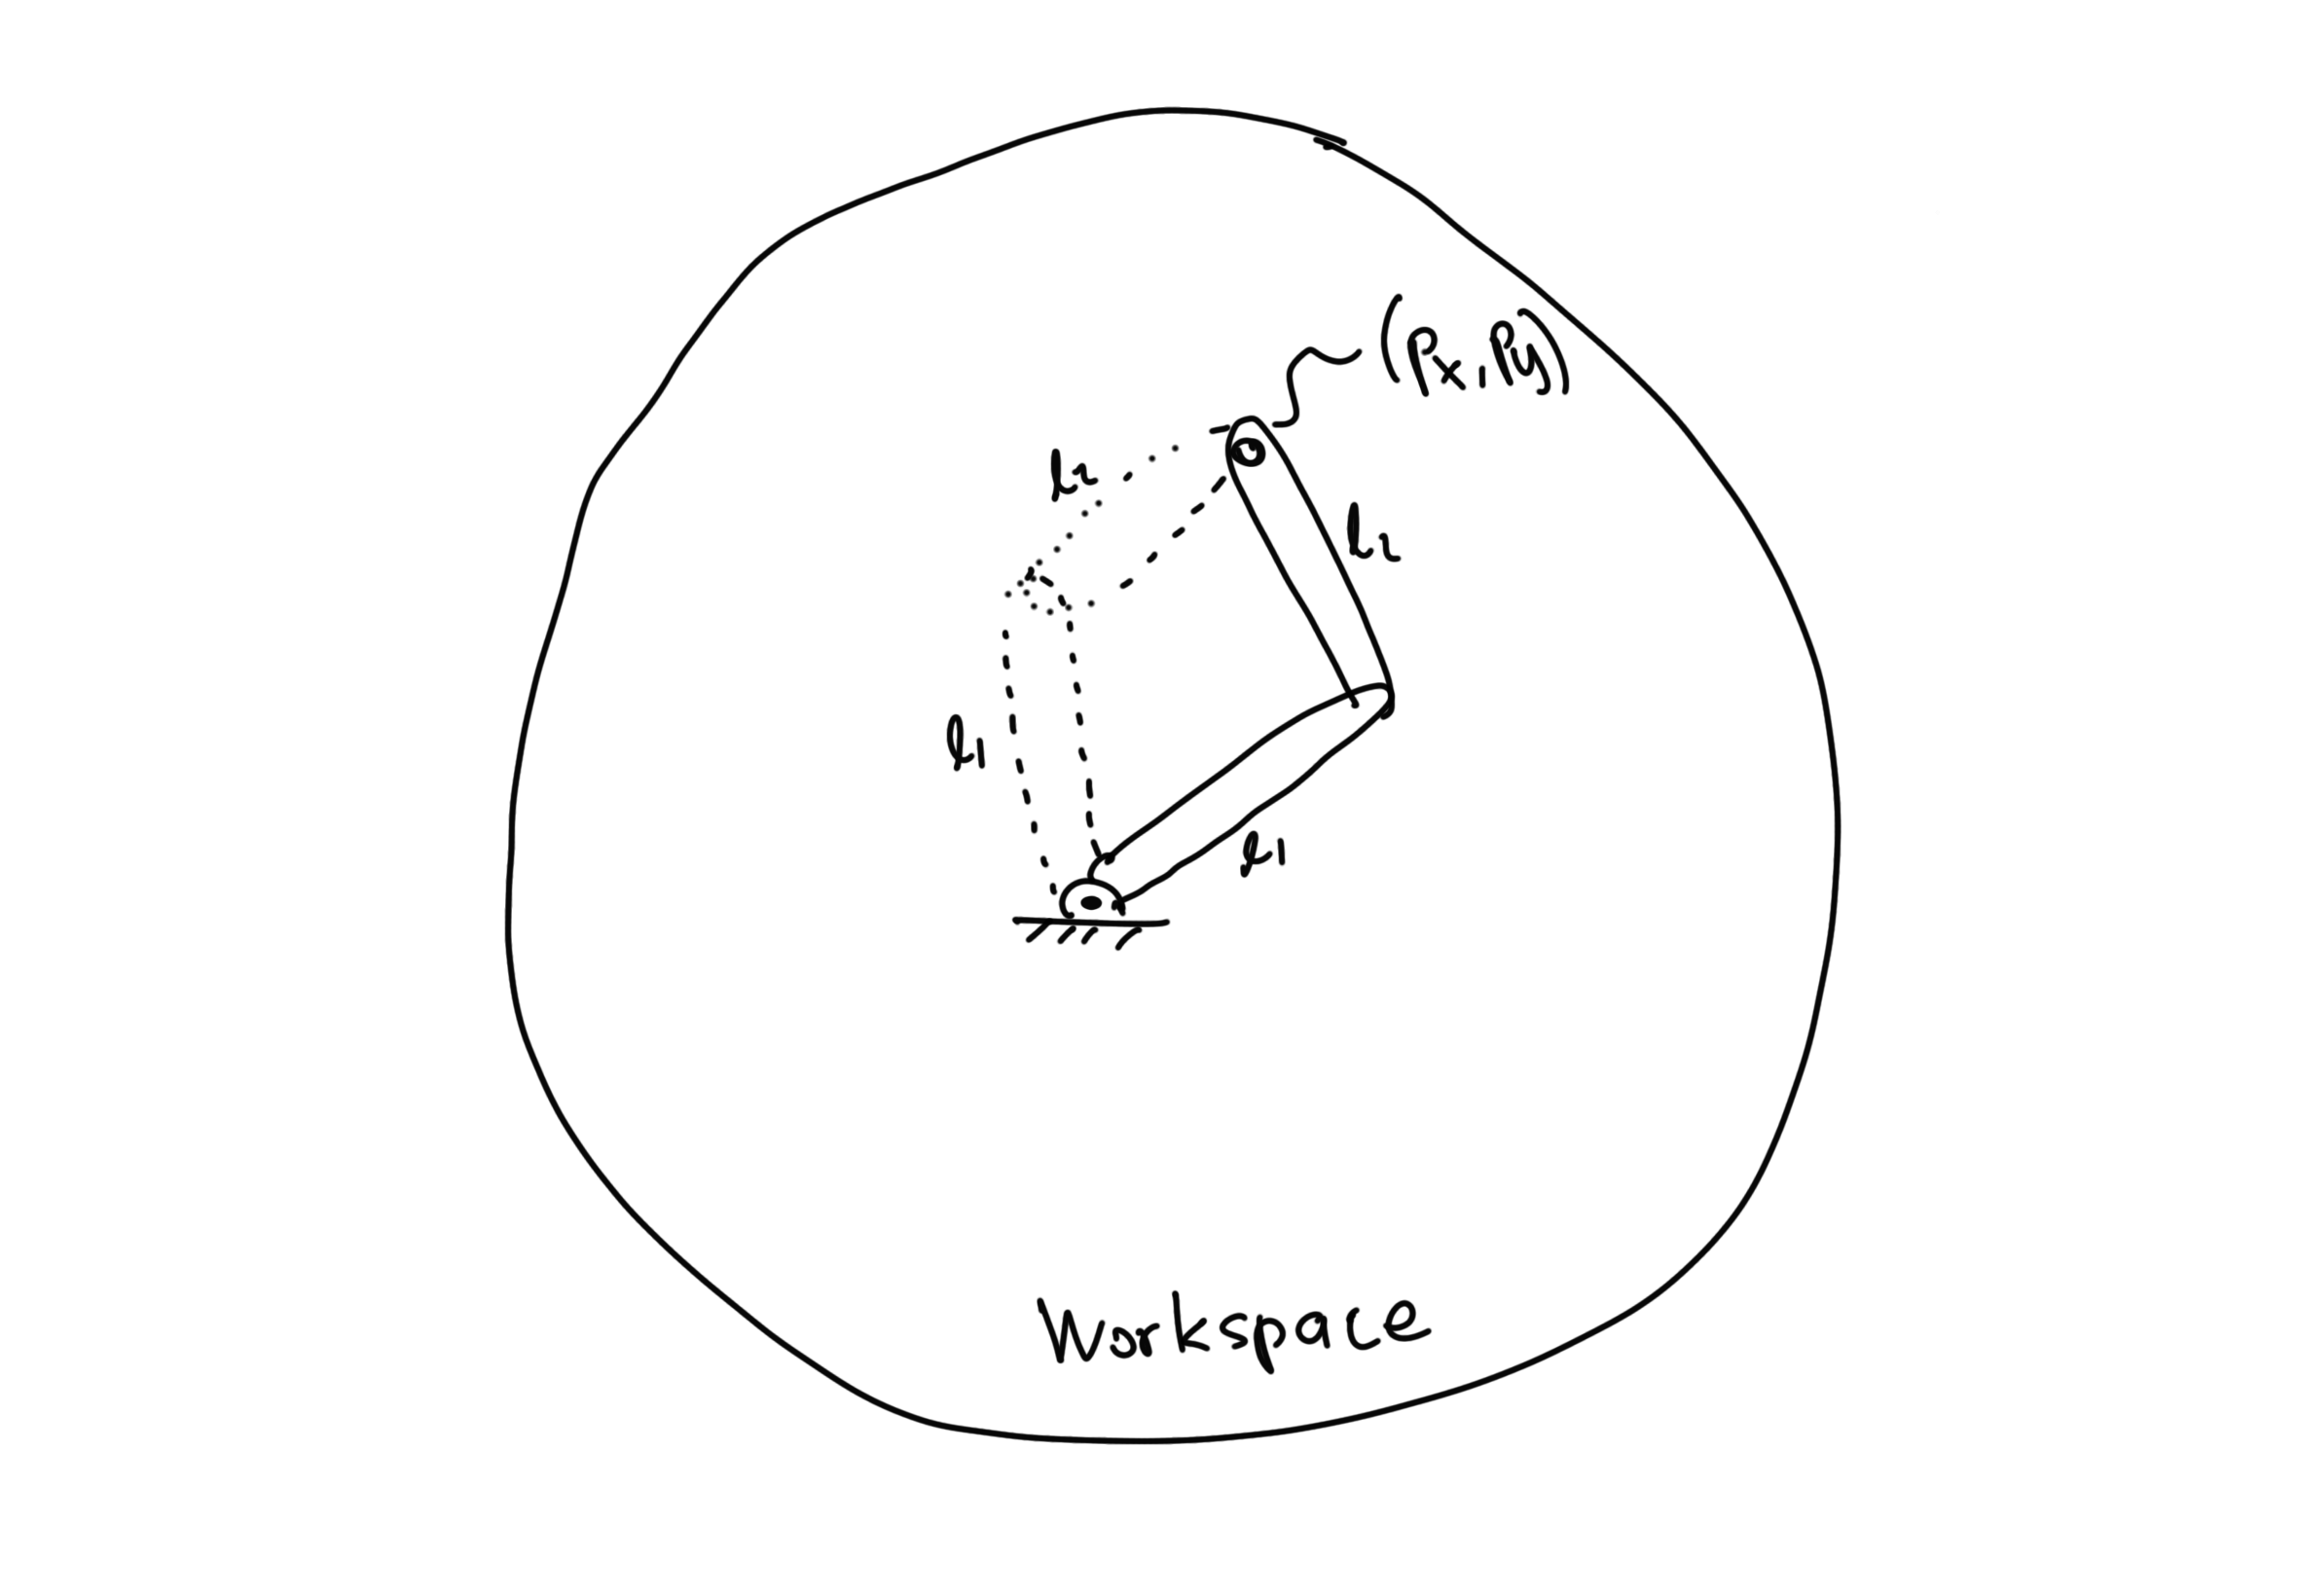

**Figure 5.8: **Workspace of 2R robot with two feasible configurations possible within the workspace.

We will consider the "righty" configuration to derive the solution, as shown in Figure 5.9. The "lefty" solution can be obtained using an analogous procedure.

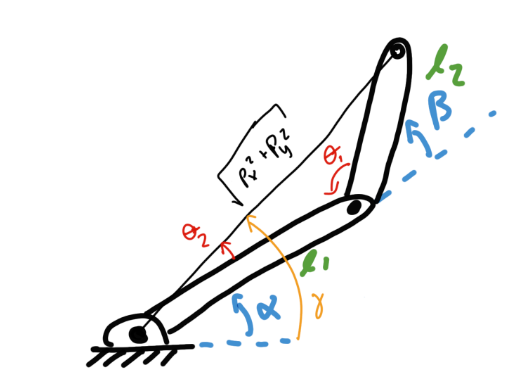

**Figure 5.9: **Righty configuration when determining geometric solution to inverse kinematic problem.

Recall that the law of cosines is given by 

$c^2=a^2+b^2-2ab\cos\theta$,

where $a$, $b$, and $c$ are the lengths of the three sides of a triangle, and $\theta$ is the interior angle opposite the side of length $c$. Referring to the figure above, angle $\theta\in[0,\pi]$ can be determined from the law of cosines 

$l_1^2+l_2^2-2l_1l_2\cos\theta_1={p^*_x}^2+{p^*_y}^2$,

from which it follows that


$$\theta_1=\cos^{-1}\left(\frac{l_1^2+l_2^2-{p_x^*}^2-{p_y^*}^2}{2l_1l_2}\right).$$


Similarly, it can easily be shown that


$$\theta_2=\cos^{-1}\left(\frac{{p_x^*}^2+{p_y^*}^2+l_1^2-l_2^2}{2l_1\sqrt{{p_x^*}^2+{p_y^*}^2}}\right).$$


Angle $\gamma$ is determined using the (two-argument) arctangent function (in `MATLAB` this is achieved using the `atan2` function) as

$\gamma=\tan^{-1}\frac{p^*_y}{p^*_x}$.

With all above angles known, the "righty" solution is determined by solving


$$\begin{array}{cc}\left[\begin{array}{cc}    \alpha \\    \beta \\    \\ \end{array}\right] =     \left[\begin{array}{cc}    \gamma-\theta_2\\    \pi-\theta_1\\    \\ \end{array}\right].\end{array}$$


The "lefty" solution can be determined by considering mirror the configuration about the line joining the base and $(p_x,p_y)$, which yields


$$\begin{array}{cc}\left[\begin{array}{cc}    \alpha \\    \beta \\    \\ \end{array}\right] =     \left[\begin{array}{cc}    \gamma+\theta_2\\    \theta_1-\pi\\    \\ \end{array}\right].\end{array}$$


If $\sqrt{{p_x^*}^2+{p_y^*}^2}$ lies outside the range $[l_1-l_2,l_1+l_2]$, then no solution exists, whereas if $\sqrt{{p_x^*}^2+{p_y^*}^2}=l_1-l_2$ (implying $\beta=\pm\pi$) or $\sqrt{{p_x^*}^2+{p_y^*}^2}=l_1+l_2$ (implying $\beta=0$), there will be a unique solution — the "lefty" and "righty" solutions will be equivalent.

### 5.6.3 Numerical optimisation 

In the context of a generalised $N$-degree-of-freedom robot manipulator, the objective of the inverse kinematic problem is to set the joint angles such that the forward kinematics matches the desired pose. This description fits neatly into an optimisation problem, where minimising the error between the forward kinematic solution and desired pose is our aim. Specifically, we want to find


$$\begin{array}{cc}\min_{\alpha,\beta} ||\mathcal{K}({\mathbf x})-{^W{\mathbf \xi}_B^\ast} ||, \end{array}$$


where  ${\mathbf x}=[\alpha,\beta]^T$. In the case of the 2R robot, we would need to collapse to a two-dimensional task space to find a feasible configuration that can achieve the desired end-effector position. The adjusted optimisation would be


$$\begin{array}{cc}\min_{\alpha,\beta} || {\bf M}\left(\mathcal{K}({\mathbf x})-{^W{\mathbf \xi}_B^\ast}\right) ||, \end{array}$$


where ${\bf M} = \left[\begin{array}{cccccccccccccc}    0 & 1 & 0 \\    0 & 0 & 1    \\ \end{array}\right]\end{array}$ is a selection matrix that extracts the first two elements (the description of position) from the pose vector. In order to minimise the above equation, we would first need to specify an initial guess for $\{\alpha,\beta\}$, namely $\{\alpha_0,\beta_0\}$. The resulting joint angles determined from this scheme will implicitly determine the orientation of the end-effector and this will ultimately depend on our initial choice of $\{\alpha_0,\beta_0\}$. 

#### Example: Using numerical optimisation to determine inverse kinematic solution

The code block below shows an example of how to determine the numerical inverse kinematic solution using an optimisation routine.

We should notice that:

- we cannot obtain the desired position if $\sqrt{{p_x^*}^2+{p_y^*}^2}$ lies outside the range $[l_1-l_2,l_1+l_2]$ — in other words, outside our workspace;

- while two solutions exist for the 2R robot when $\mathcal{T}\subset\mathbb{R}^2$, the optimisation process will return a single solution, which will be the solution closest to the initial guess.

l1 = 1;
l2 = 0.5;

robot = rigidBodyTree("DataFormat","column");
manipulatorBase = rigidBody('manipulatorBase');
%joint1
baseJoint = rigidBodyJoint('baseJoint','revolute');
baseJoint.JointAxis = [0 0 1];
baseJoint.HomePosition = 0;
p_joint1 = [0, 0, 0];
tform = trvec2tform(p_joint1);
setFixedTransform(baseJoint,tform);
manipulatorBase.Joint = baseJoint;
addBody(robot,manipulatorBase,'base');
%joint2 and link1
link1 = rigidBody('link1');
elbowJoint = rigidBodyJoint('elbowJoint','revolute');
elbowJoint.JointAxis = [0 0 1];
elbowJoint.HomePosition = 0;
p_joint2 = [l1, 0, 0];
tform2 = trvec2tform(p_joint2);
setFixedTransform(elbowJoint,tform2);
link1.Joint = elbowJoint;
addBody(robot,link1,'manipulatorBase');
%link2 and end-effector
link2 = rigidBody('link2');
endEffectorJoint = rigidBodyJoint('endEffectorJoint');
tform3 = trvec2tform([l2, 0, 0]);
setFixedTransform(endEffectorJoint,tform3);
link2.Joint = endEffectorJoint;
addBody(robot,link2,'link1');


px_des =0.9; 
py_des =1.3;    %desired x-y location of end-effector

q_guess = [0 0]' %initial guess of configuration.

q_guess =      0
     0



options = optimset('fzero');    %sets the minimisation tolerance of e to "zero" — actually about 2.2e-16.
e = @(x_) ( l1*cos( x_(1) )+l2*cos( x_(1)+x_(2) )-px_des )^2 + ( l1*sin( x_(1) )+l2*sin( x_(1)+x_(2) )-py_des )^2;
x_opt = fminsearch( e, q_guess,options )

x_opt =     0.9653
   -0.0000



fig = figure(1),clf;

fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 360 560 420]
       Units: 'pixels'

  Show all properties


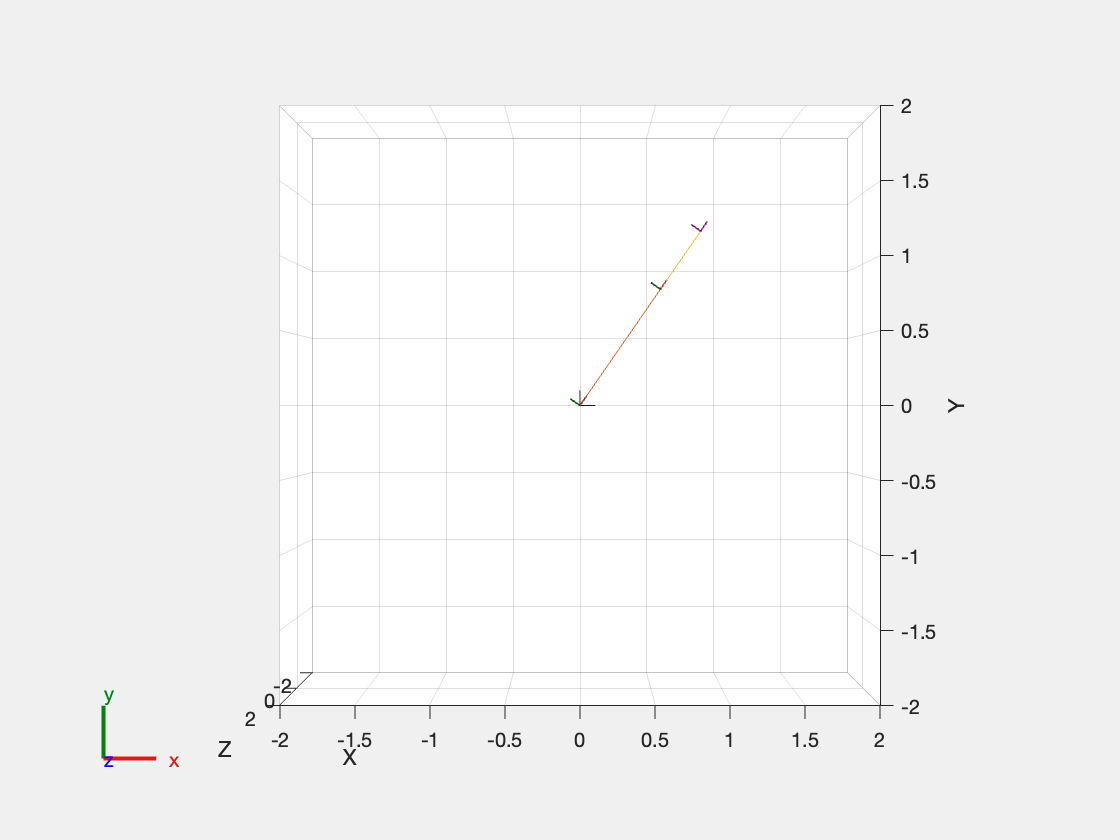

show(robot,x_opt,"Parent",axes(fig));
view(2)

While this approach is demonstrated using a 2R robot arm, this method can be abstracted to systems that contain large amounts of links. 